# File Name: Search_Registration_03_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Find Radial Neighbors in Point Cloud

Load a set of 3-D coordinate points into the workspace.

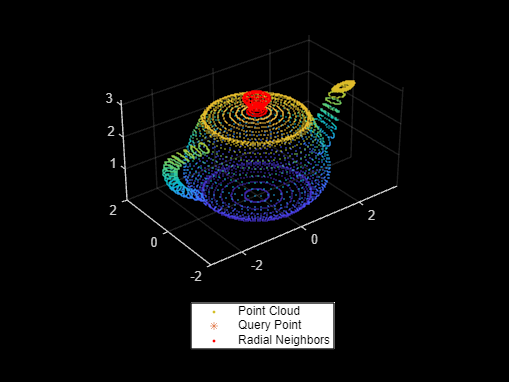

load('xyzPoints.mat');

% Create a point cloud object.
ptCloud = pointCloud(xyzPoints);

% Specify a query point and the radius within which the neighbors are to be identified.
point = [0,0,3];
radius = 0.5;

%%%%%%%%%% TODO %%%%%%%%%%
% Get the indices and the distances of points that lie within the specified radius.
[indices,dists] = findNeighborsInRadius(ptCloud,point,radius);

% Get the point cloud data of radial neighbors.
ptCloudB = select(ptCloud,indices);

% Display the point cloud. Plot the query point and the corresponding radial neighbors.
figure
pcshow(ptCloud)
hold on
plot3(point(1),point(2),point(3),'*')
pcshow(ptCloudB.Location,'r')
legend('Point Cloud','Query Point','Radial Neighbors','Location','southoutside','Color',[1 1 1])
hold off